# Alireza Amiri | Iman Gandomi

# Robotics Project Codes - Part2

## Question 1

% Define symbolic variables
syms theta1(t) theta2(t) theta3(t) % Declare theta1 and theta2 as functions of time
syms dtheta1 dtheta2 dtheta3 real  % Declare the time derivatives of theta1 and theta2

% Define the rotation matrix R
R = [ -cos(theta1)*cos(theta2), cos(theta1)*sin(theta2), sin(theta1);
      -sin(theta2),            -cos(theta2),           0;
       cos(theta2)*sin(theta1), -sin(theta1)*sin(theta2), cos(theta1)];

% Differentiate the matrix with respect to time
R_dot = diff(R, t);

% Simplify the result
R_dot = simplify(R_dot);

% Display the result
disp('Time derivative of R:');

Time derivative of R:


disp(R_dot);

$$\left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)+\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & \cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right) & \cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ -\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & \sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0\\ \cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)-\cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & -\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$


%%

R_transpose = R.'

$$R\_transpose(t) = \left(\begin{array}{ccc} -\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right) & -\cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\\ \sin\left(\theta_{1}\left(t\right)\right) & 0 & \cos\left(\theta_{1}\left(t\right)\right) \end{array}\right)$$


omega_cross = simplify(R_dot*R_transpose)

$$omega\_cross(t) = \left(\begin{array}{ccc} 0 & -\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & \frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 & -\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ -\frac{\partial }{\partial t}\theta_{1}\left(t\right) & \sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) & 0 \end{array}\right)$$

jw = [0 sin(theta1) 0;
     1 0 0;
     0 cos(theta1) 0]

$$jw(t) = \left(\begin{array}{ccc} 0 & \sin\left(\theta_{1}\left(t\right)\right) & 0\\ 1 & 0 & 0\\ 0 & \cos\left(\theta_{1}\left(t\right)\right) & 0 \end{array}\right)$$

% Define the time derivatives
dtheta1 = diff(theta1, t);
dtheta2 = diff(theta2, t);
dtheta3 = diff(theta3, t);

% Define the joint velocity vector
theta_dot = [dtheta1; dtheta2; dtheta3];

% Calculate the angular velocity
angular_velocity = jw * theta_dot;
disp(angular_velocity)

$$\left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ \cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$



% Display the results
disp('angular velocity components:');

angular velocity components:


% Define omega_cross matrix
omega_cross = [
    0, -cos(theta1) * dtheta2, dtheta1;
    cos(theta1) * dtheta2, 0, -sin(theta1) * dtheta2;
    -dtheta1, sin(theta1) * dtheta2, 0
];

%%
syms theta1 theta2 theta3 l1 l5 % Define symbolic variables

% Define the vector p
p = [cos(theta1)*(l1*cos(theta3) - l5*cos(theta2));
     l1*sin(theta3) - l5*sin(theta2);
     -sin(theta1)*(l1*cos(theta3) - l5*cos(theta2))];

% Calculate partial derivatives
dp_dtheta1 = diff(p, theta1); % Partial derivative with respect to theta1
dp_dtheta2 = diff(p, theta2); % Partial derivative with respect to theta2
dp_dtheta3 = diff(p, theta3); % Partial derivative with respect to theta3

% Combine the derivatives into a 3x3 matrix
Jacobian_matrix = [dp_dtheta1, dp_dtheta2, dp_dtheta3];

% Display the Jacobian matrix
disp('Jacobian matrix (3x3) of partial derivatives:');

Jacobian matrix (3x3) of partial derivatives:


disp(Jacobian_matrix);

$$\begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\right)\,\sigma_{1} & l_{5}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -l_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ 0 & -l_{5}\,\cos\left(\theta_{2}\right) & l_{1}\,\cos\left(\theta_{3}\right)\\ -\cos\left(\theta_{1}\right)\,\sigma_{1} & -l_{5}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & l_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{3}\right)-l_{5}\,\cos\left(\theta_{2}\right) \end{array}$$

% Define the joint velocity vector
theta_dot = [dtheta1; dtheta2; dtheta3];

% Calculate the linear velocity
velocity = Jacobian_matrix * theta_dot;

% Display the results
disp('Linear velocity components:');

Linear velocity components:



disp(velocity(1))

$$\begin{array}{l} \left(\begin{array}{c} l_{5}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)|}_{t=1}\right)-l_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)|}_{t=1}\right)-\sin\left(\theta_{1}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)|}_{t=1}\right)\,\sigma_{1}\\ l_{1}\,\cos\left(\theta_{3}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)|}_{t=1}\right)-l_{5}\,\cos\left(\theta_{2}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)|}_{t=1}\right)\\ l_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{3}\left(t\right)\right)|}_{t=1}\right)-\cos\left(\theta_{1}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)|}_{t=1}\right)\,\sigma_{1}-l_{5}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left({\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)|}_{t=1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{3}\right)-l_{5}\,\cos\left(\theta_{2}\right) \end{array}$$

## Question 2

% Define symbolic variables
syms t l1 l5 real           % Time and constants
syms theta1(t) theta2(t) theta3(t) % Angles as functions of time

% Define the actual trigonometric terms
S1 = sin(theta1);
C1 = cos(theta1);
S2 = sin(theta2);
C2 = cos(theta2);
S3 = sin(theta3);
C3 = cos(theta3);

% Define the given q1, q2, q3
q1 = (pi/6)*sin(t);
q2 = (pi/6)*sin(t) + pi/4;
q3 = (pi/8)*sin(t) + (3*pi/4);

% Create q as a vector and compute its time derivative
q = [q1; q2; q3];
q_dot = diff(q, t);  % True time derivative of q

% Define the Jacobian matrix J with actual sine and cosine terms
J = [ -sin(theta1)*(l1*cos(theta3) - l5*cos(theta2)), l5*cos(theta1)*sin(theta2), -l1*cos(theta1)*sin(theta3);
       0,                                              -l5*cos(theta2),            l1*cos(theta3);
      -cos(theta1)*(l1*cos(theta3) - l5*cos(theta2)), -l5*sin(theta1)*sin(theta2), l1*sin(theta1)*sin(theta3);
       0,                                            sin(theta1),                           0;
       1,                                            0,                           0;
       0,                                            cos(theta1),                 0];

% Multiply Jacobian matrix J by q_dot
result = simplify(J * q_dot);

% Display the results
disp('Time derivative of q (q_dot):');

Time derivative of q (q_dot):


disp(q_dot);

$$\left(\begin{array}{c} \frac{\pi \,\cos\left(t\right)}{6}\\ \frac{\pi \,\cos\left(t\right)}{6}\\ \frac{\pi \,\cos\left(t\right)}{8} \end{array}\right)$$

disp('Result of J * q_dot:');

Result of J * q_dot:


disp(result);

$$\begin{array}{l} \left(\begin{array}{c} \frac{\pi \,l_{5}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(t\right)}{6}-\frac{\pi \,l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\,\cos\left(t\right)}{8}-\frac{\pi \,\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(t\right)\,\sigma_{1}}{6}\\ \frac{\pi \,l_{1}\,\cos\left(\theta_{3}\left(t\right)\right)\,\cos\left(t\right)}{8}-\frac{\pi \,l_{5}\,\cos\left(\theta_{2}\left(t\right)\right)\,\cos\left(t\right)}{6}\\ \frac{\pi \,l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\,\cos\left(t\right)}{8}-\frac{\pi \,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(t\right)\,\sigma_{1}}{6}-\frac{\pi \,l_{5}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right)\,\cos\left(t\right)}{6}\\ \frac{\pi \,\sin\left(\theta_{1}\left(t\right)\right)\,\cos\left(t\right)}{6}\\ \frac{\pi \,\cos\left(t\right)}{6}\\ \frac{\pi \,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(t\right)}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\theta_{3}\left(t\right)\right)-l_{5}\,\cos\left(\theta_{2}\left(t\right)\right) \end{array}$$

J

$$J(t) = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(\theta_{1}\left(t\right)\right)\,\left(\sigma_{2}-\sigma_{1}\right) & l_{5}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right) & -l_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ 0 & -\sigma_{1} & \sigma_{2}\\ -\cos\left(\theta_{1}\left(t\right)\right)\,\left(\sigma_{2}-\sigma_{1}\right) & -l_{5}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{2}\left(t\right)\right) & l_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ 0 & \sin\left(\theta_{1}\left(t\right)\right) & 0\\ 1 & 0 & 0\\ 0 & \cos\left(\theta_{1}\left(t\right)\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{5}\,\cos\left(\theta_{2}\left(t\right)\right)\\ \sigma_{2}=l_{1}\,\cos\left(\theta_{3}\left(t\right)\right) \end{array}$$

## Question 4

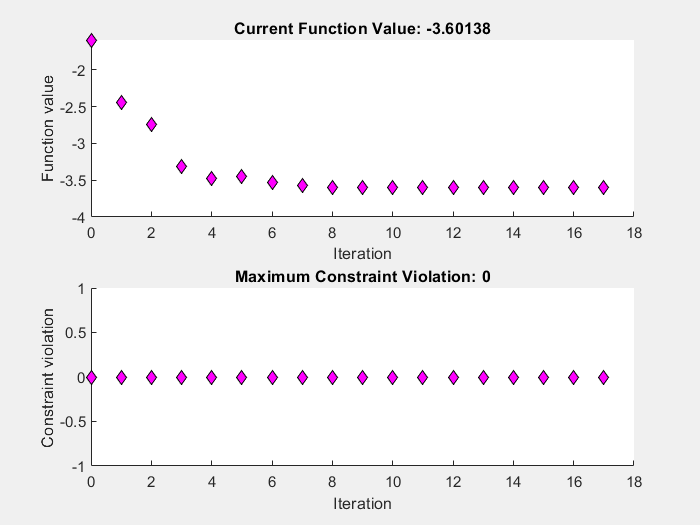


Optimization completed: The relative first-order optimality measure, 5.480834e-09,
is less than options.OptimalityTolerance = 1.000000e-08, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.



% MATLAB Script to Maximize the Magnitude of tau and Visualize the Function

% Clear workspace and command window
clear; clc; close all;

% Define constants (ensure l1 and l5 are positive)
l1 = 1.28;  % Example value for l1
l5 = 1.35;  % Example value for l5

%% Optimization to Maximize ||tau||

% Define the objective function to maximize ||tau||
% Since fmincon minimizes, we minimize the negative norm
objective = @(x) -norm([
    -sin(x(1))*(l1*cos(x(3)) - l5*cos(x(2))) - cos(x(1))*(l1*cos(x(3)) - l5*cos(x(2))),
    l5*cos(x(1))*sin(x(2)) - l5*cos(x(2)) - l5*sin(x(1))*sin(x(2)),
    -l1*cos(x(1))*sin(x(3)) + l1*cos(x(3)) + l1*sin(x(1))*sin(x(3))
]);



% Initial guess for [theta1, theta2, theta3] in radians
x0 = [0, pi/4, pi/2];  % A feasible initial guess within the specified bounds

% Define bounds for theta1, theta2, theta3
lb = [-pi/2, 0, pi/4];        % Lower bounds
ub = [ pi/2, pi/2, 3*pi/4];  % Upper bounds

% lb = [-10, -10, -10];        % Lower bounds
% ub = [ 10, 10, 10];  % Upper bounds

% Set optimization options
options = optimoptions('fmincon', ...
    'Algorithm', 'interior-point', ...         % Switched to 'interior-point' for better handling of large-scale problems
    'Display', 'final-detailed', ...           % Show detailed results at the end of optimization
    'MaxIterations', 500, ...                  % Limit the number of iterations to 500
    'MaxFunctionEvaluations', 1e5, ...         % Increase function evaluations to handle complex problems
    'OptimalityTolerance', 1e-8, ...           % Stricter tolerance for optimality
    'StepTolerance', 1e-8, ...                 % Stricter step tolerance
    'ConstraintTolerance', 1e-6, ...           % Add explicit constraint tolerance
    'FiniteDifferenceType', 'central', ...     % Use central differences for gradient approximation for better accuracy
    'FiniteDifferenceStepSize', 1e-5, ...      % Small step size for finite difference approximation
    'HessianApproximation', 'lbfgs', ...       % Approximate the Hessian using L-BFGS for memory efficiency
    'CheckGradients', true, ...                % Enable gradient checking for debugging
    'PlotFcn', {@optimplotfval, @optimplotconstrviolation} ... % Plot function value and constraint violation
    );           % Add a custom output function to monitor progress


% Perform the optimization using fmincon
% No nonlinear constraints, so set them to empty
[x_opt, fval, exitflag, output] = fmincon(objective, x0, [], [], [], [], lb, ub, [], options);


% Check if optimization was successful
if exitflag <= 0
    warning('Optimization did not converge to a solution.');
end

% Extract optimal angles
theta1_opt = x_opt(1);
theta2_opt = x_opt(2);
theta3_opt = x_opt(3);

% Calculate the maximum norm of tau
max_tau_norm = -fval;

% Display the results
fprintf('Optimal Angles (radians):\n');

Optimal Angles (radians):


fprintf('theta1 = %.4f rad (%.2f°)\n', theta1_opt, rad2deg(theta1_opt));

theta1 = 0.6492 rad (37.20°)


fprintf('theta2 = %.4f rad (%.2f°)\n', theta2_opt, rad2deg(theta2_opt));

theta2 = 0.0000 rad (0.00°)


fprintf('theta3 = %.4f rad (%.2f°)\n', theta3_opt, rad2deg(theta3_opt));

theta3 = 2.3562 rad (135.00°)


fprintf('Maximum ||tau|| = %.4f\n', max_tau_norm);

Maximum ||tau|| = 3.6014



% (Optional) Display the optimal tau vector
tau_opt = [
    -sin(theta1_opt)*(l1*cos(theta3_opt) - l5*cos(theta2_opt)) - cos(theta1_opt)*(l1*cos(theta3_opt) - l5*cos(theta2_opt)),
    l5*cos(theta1_opt)*sin(theta2_opt) - l5*cos(theta2_opt) - l5*sin(theta1_opt)*sin(theta2_opt),
    -l1*cos(theta1_opt)*sin(theta3_opt) + l1*cos(theta3_opt) + l1*sin(theta1_opt)*sin(theta3_opt)
];


fprintf('Optimal tau vector:\n');

Optimal tau vector:


fprintf('[%.4f, %.4f, %.4f]\n', tau_opt(1), tau_opt(2), tau_opt(3));

[3.1597, -1.3500, -1.0789]


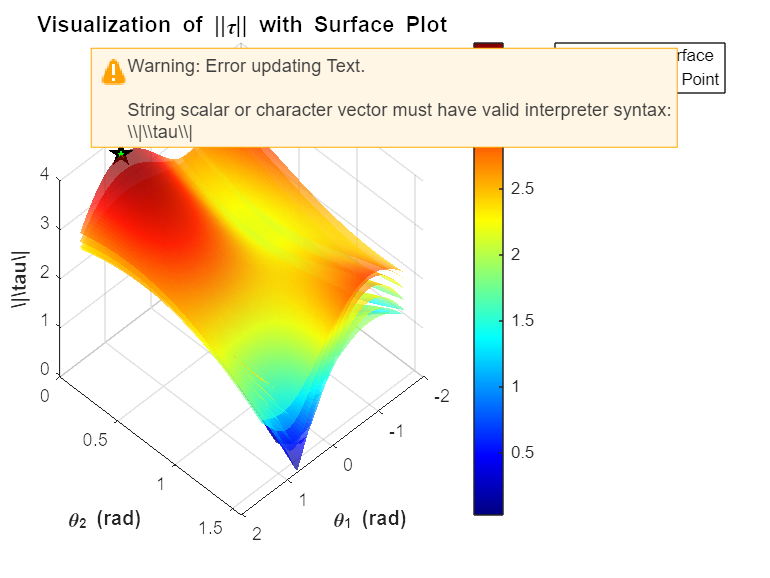


%% Visualization: 3D Scatter Plot with Color Representing ||tau||

% Define the number of sample points for each variable
num_theta1 = 100;
num_theta2 = 100;
num_theta3 = 100;

% Generate a grid of theta1, theta2, theta3 within the specified bounds
theta1_vals = linspace(lb(1), ub(1), num_theta1);
theta2_vals = linspace(lb(2), ub(2), num_theta2);
theta3_vals = linspace(lb(3), ub(3), num_theta3);

% Create a meshgrid for theta1, theta2, theta3
[Theta1, Theta2, Theta3] = ndgrid(theta1_vals, theta2_vals, theta3_vals);

% Reshape the grids into vectors for easy computation
Theta1_vec = Theta1(:);
Theta2_vec = Theta2(:);
Theta3_vec = Theta3(:);

% Preallocate a vector to store ||tau|| values
tau_norm_vec = zeros(size(Theta1_vec));

% Compute ||tau|| for each combination of theta1, theta2, theta3
for i = 1:length(Theta1_vec)
    tau = [
        -sin(Theta1_vec(i))*(l1*cos(Theta3_vec(i)) - l5*cos(Theta2_vec(i))) - cos(Theta1_vec(i))*(l1*cos(Theta3_vec(i)) - l5*cos(Theta2_vec(i))),
        l5*cos(Theta1_vec(i))*sin(Theta2_vec(i)) - l5*cos(Theta2_vec(i)) - l5*sin(Theta1_vec(i))*sin(Theta2_vec(i)),
        -l1*cos(Theta1_vec(i))*sin(Theta3_vec(i)) + l1*cos(Theta3_vec(i)) + l1*sin(Theta1_vec(i))*sin(Theta3_vec(i))
    ];


    tau_norm_vec(i) = norm(tau);
end

% Reshape the computed ||tau|| values to match the grid dimensions
tau_norm_grid = reshape(tau_norm_vec, size(Theta1));

% Reshape the computed ||tau|| values to match the grid dimensions
tau_norm_grid = reshape(tau_norm_vec, size(Theta1));

% Create a surface plot with multiple slices
figure('Name', 'Visualization of ||tau|| with Surface Plot', 'NumberTitle', 'off');

% Define more slice indices for better visualization
num_slices = 7; % Number of slices
slice_indices = round(linspace(1, num_theta3, num_slices)); % Evenly spaced slices along theta3

% Plot the slices
for i = 1:length(slice_indices)
    slice_data = tau_norm_grid(:, :, slice_indices(i));
    surf(Theta1(:, :, 1), Theta2(:, :, 1), slice_data, 'FaceAlpha', 0.7, 'EdgeColor', 'none');
    hold on;
end

xlabel('\theta_1 (rad)', 'FontWeight', 'bold');
ylabel('\theta_2 (rad)', 'FontWeight', 'bold');
zlabel('\|\tau\|', 'FontWeight', 'bold');
title('Visualization of ||\tau|| with Surface Plot', 'FontSize', 12, 'FontWeight', 'bold');
colorbar;
colormap('jet');
view(135, 45); % Set a 3D view angle
grid on;

% Highlight the optimal point found by optimization
scatter3(theta1_opt, theta2_opt, max_tau_norm, 100, 'p', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'g', 'LineWidth', 1.5);
legend('||\tau|| Surface', 'Optimal Point');
hold off;